clc
clear

# Creating GSPNR with Topological Map Code Example

Creating topological map:

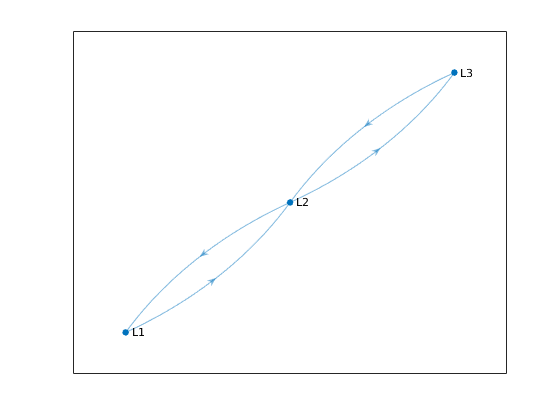

adjacency_matrix = [0 1 0;
                    1 0 1;
                    0 1 0];
topological_map = digraph(adjacency_matrix, {'L1' 'L2' 'L3'}, 'omitselfloops');
plot(topological_map)

Defining which actions the robots can execute in each location:

actions_available.L1 = ["mopping", "vacuuming"];
actions_available.L2 = ["mopping", "vacuuming"];
actions_available.L3 = ["mopping", "vacuuming"];

Defining the robots' initial location:

robot_marking.L1 = 2;

Importing primitive models from GreatSPN file

PNPRO_path = "homeclean_notimeouts.PNPRO";
[nGSPN, models] = ImportfromGreatSPN(PNPRO_path);

Creating GSPNR model:

home_GSPNR = GSPNRCreationfromTopMap(topological_map, actions_available, models, robot_marking)

home_GSPNR =   GSPNR with properties:

                places: ["Mopping_L1"    "Vacuuming_L1"    "Mopping_L2"    "Vacuuming_L2"    "Mopping_L3"    "Vacuuming_L3"    "Navigating_L1_L2"    "Navigating_L2_L1"    "L1"    "Navigating_L2_L3"    "Navigating_L3_L2"    "L2"    "L3"]
           transitions: [1×20 string]
      type_transitions: ["imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"    "imm"    "exp"]
      rate_transitions: [0 0.1000 0 10 0 0.1000 0 10 0 0.1000 0 10 0 1 0 1 0 1 0 1]
            input_arcs: [13×20 double]
           output_arcs: [20×13 double]
                  arcs: [1×1 struct]
       initial_marking: [0 0 0 0 0 0 0 0 2 0 0 0 0]
       current_marking: [0 0 0 0 0 0 0 0 2 0 0 0 0]
         place_rewards: [0 0 0 0 0 0 0 0 0 0 0 0 0]
    transition_rewards: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]


Adding rewards:

reward_elements = ["Mop_L2"];
reward_types = ["transition"];
reward_values = [1];
home_GSPNR.set_reward_functions(reward_elements, reward_values, reward_types);